# Práctica 3: Problema de caminos mínimos

**Funciones de MATLAB empleadas:**

- **graph() **crea una estrucutura conteniendo un grafo.

- **digraph() **crea una estrucutura conteniendo un grafo dirigido.

- **plot()** dibuja un grafo.

- **shortestpath**() calcula el camino minimo en un grafo de un nodo inicial a otro final.

- **highlight() **resalta dentro de un grafo unos nodos o uno arcos (camino).

- Trabajar con estructuras: NombreEstructura**.**variable_estrucutura.

En esta práctica se introduce las funciones básicas para trabajar con grafos en MATLAB y se aplica al problema de caminos minimos. Finalizamos con una aplicación al diseño de trayectorias de un robot.

**Borrón y cuenta nueva!!**

clc, clear, close all

## 1. Representación de grafos

Vamos a representar un grafo (simple y dirigido) dando el listado de sus aristas (arcos). En el primer ejemplo los nodos son nombrados mediante etiquetas. En el segundo ejemplo los nodos están numerados.

Recuerda que una arista en un grafo simple está compuesta por un conjunto de dos nodos (o vértices), que son los extremos de la arista. En el caso de los dígrafos, una arista se define mediante una tupla de dos vértices (el vértice inicial y el vértice final). En MATLAB necesitamos definir dos listas, una para los vértices iniciales y otra para los finales. Cada lista puede definirse como una lista de enteros, un cell de chars o un cell de strings. Nótese que si queremos definir un grafo no dirigido, no hay diferencia entre la lista de vértices iniciales y la de vértices finales.

### Nodos con etiquetas

% Listado de los nodos de los arcos
source_nodes = {'A','A','B'}; % Notar que es un cell de chars
% Listado de los nodos de los arcos
target_nodes = {'B','C','C'};  
% Peso de los arcos 
edge_weights = [1 2 3]; % Vector de números reales

Vamos a crear el grafo, consistente en una **estructura** formada por aristas (Edges) y nodos (Nodes)

G = graph(source_nodes, target_nodes, edge_weights)

G =   graph with properties:

    Edges: [3×2 table]
    Nodes: [3×1 table]


Podemos examinar los elementos del grafo, escribiendo

G.Edges % muestra el elemento "Table" que define las aristas

ans = 3×2 table
       EndNodes       Weight
    ______________    ______

    {'A'}    {'B'}      1   
    {'A'}    {'C'}      2   
    {'B'}    {'C'}      3   


G.Edges.Weight % muestra el vector de pesos de las aristas

ans =      1
     2
     3


G.Edges.Weight(2)=8 % cambiamos el peso de la segunda arista

G =   graph with properties:

    Edges: [3×2 table]
    Nodes: [3×1 table]


Vamos a representar el grafo

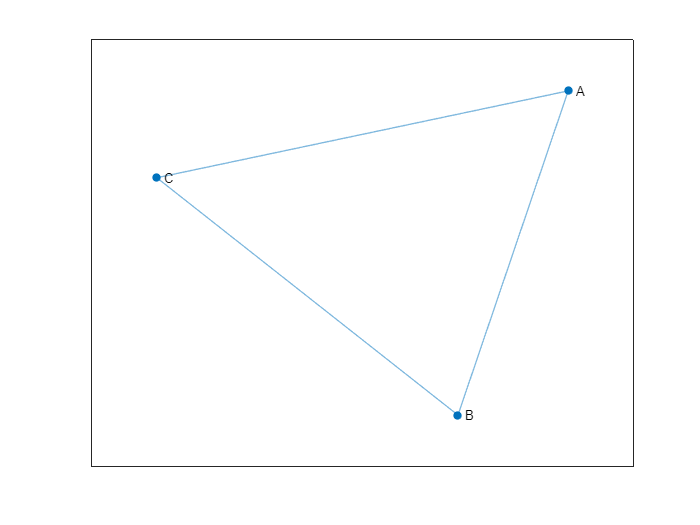

figure(1)
p = plot(G);

**EJERCICIO: **Un grafo dirigido se construye de la misma manera pero ahora el vector source_nodes son los origenes de los arcos y target_nodes los destinos. La sentencia para construir el grafo es *digraph***. **Se pide:

- Mostrar un grafo dirigido que recorra el triángulo anterior en el orden A - C - B - A

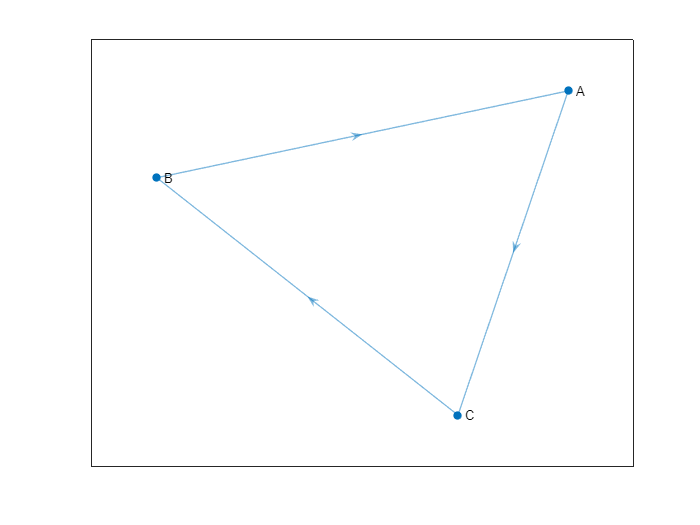

%% Completar con el código correspondiente
Source = {'A', 'C', 'B'};
Target = {'C', 'B', 'A'};
Weights = [1 2 3];

D = digraph(Source, Target, Weights);
figure(2)
p = plot(D);

- Repetir el ejercicio anterior pero en sentido contrario (A - B - C - A)

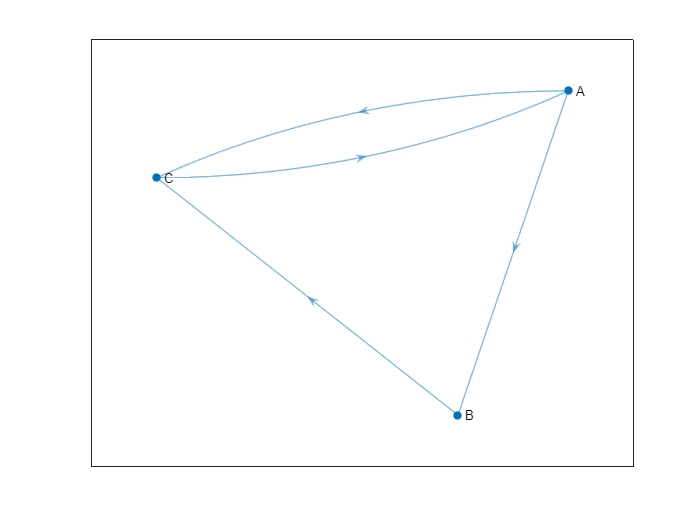

%% Completar con el código correspondiente
Source = {'A', 'B', 'C', 'A'}; %% Representar doble sentido añadiendo el contrario del nodo
Target = {'B', 'C', 'A', 'C'};
Weights = [1 2 3 3];

D2 = digraph(Source, Target, Weights);
figure(2)
p = plot(D2);

### Nodos numerados

Considerar el grafo dirigido siguiente (red de Nugyen-Dupuis) que representa una red de tráfico.

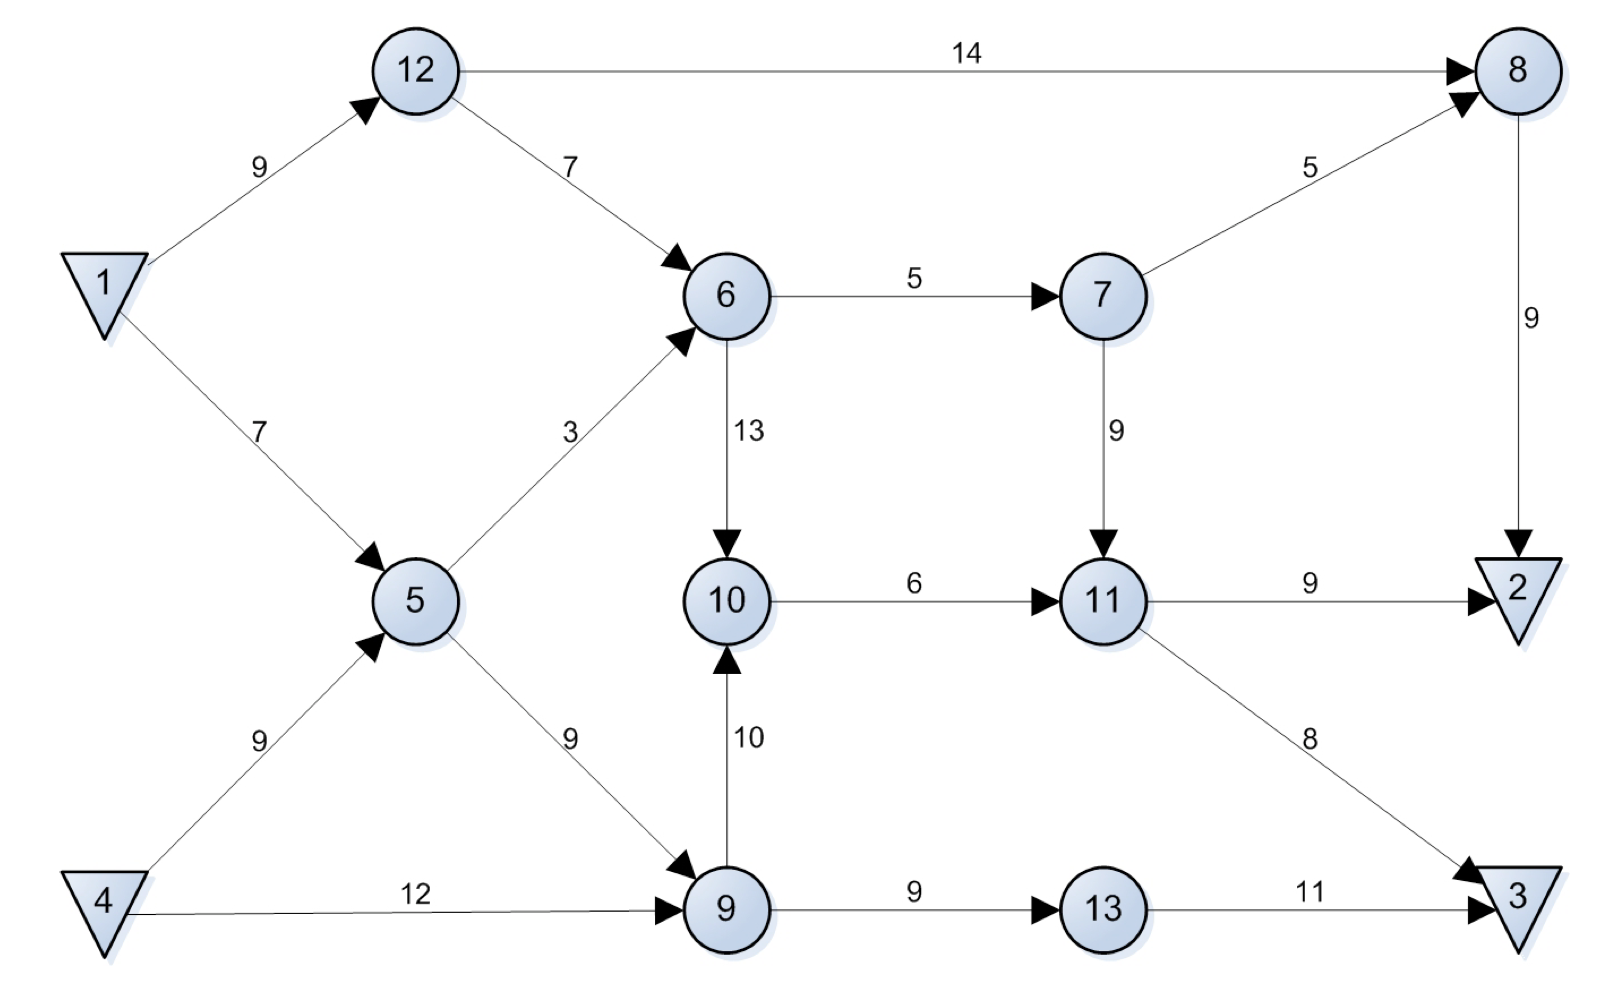

El listado de aristas viene definido por:

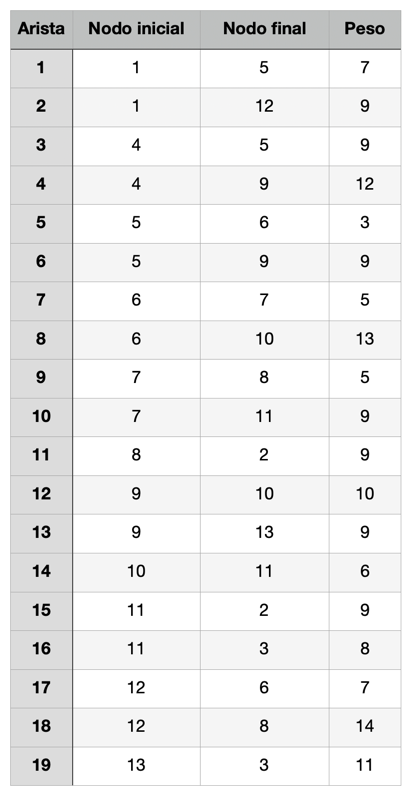

Vamos a definir el grafo dirigido:

% La introducción de los nodos origen y nodos destino se realiza mediante
% un vector de numeros enteros 
source_nodes1 = [1,1,4,4,5,5,6,6,7,7,8,9,9,10,11,11,12,12,13];
target_nodes1 = [5,12,5,9,6,9,7,10,8,11,2,10,13,11,2,3,6,8,3];
edge_weights1 = [7,9,9,12,3,9,5,13,5,9,9,10,9,6,9,8,7,14,11];
figure(2)
G1 = digraph(source_nodes1, target_nodes1, edge_weights1)

G1 =   digraph with properties:

    Edges: [19×2 table]
    Nodes: [13×0 table]


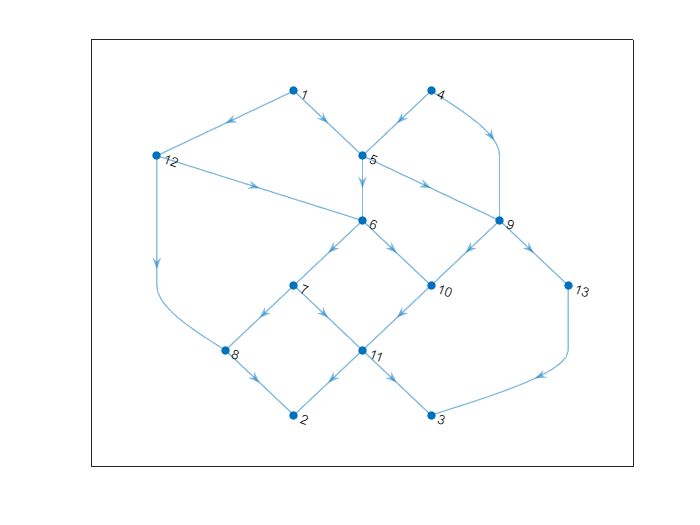

p1 = plot(G1);

### Modificación de opciones de aspecto

#### Especifiación de las coordenadas de los nodos

La visualización de MATLAB difiere de la representada en el dibujo. Si queremos obtener una representación similar tendremos que especificar las coordenadas de los nodos. Por lo que introducimos un sistema coordenado:

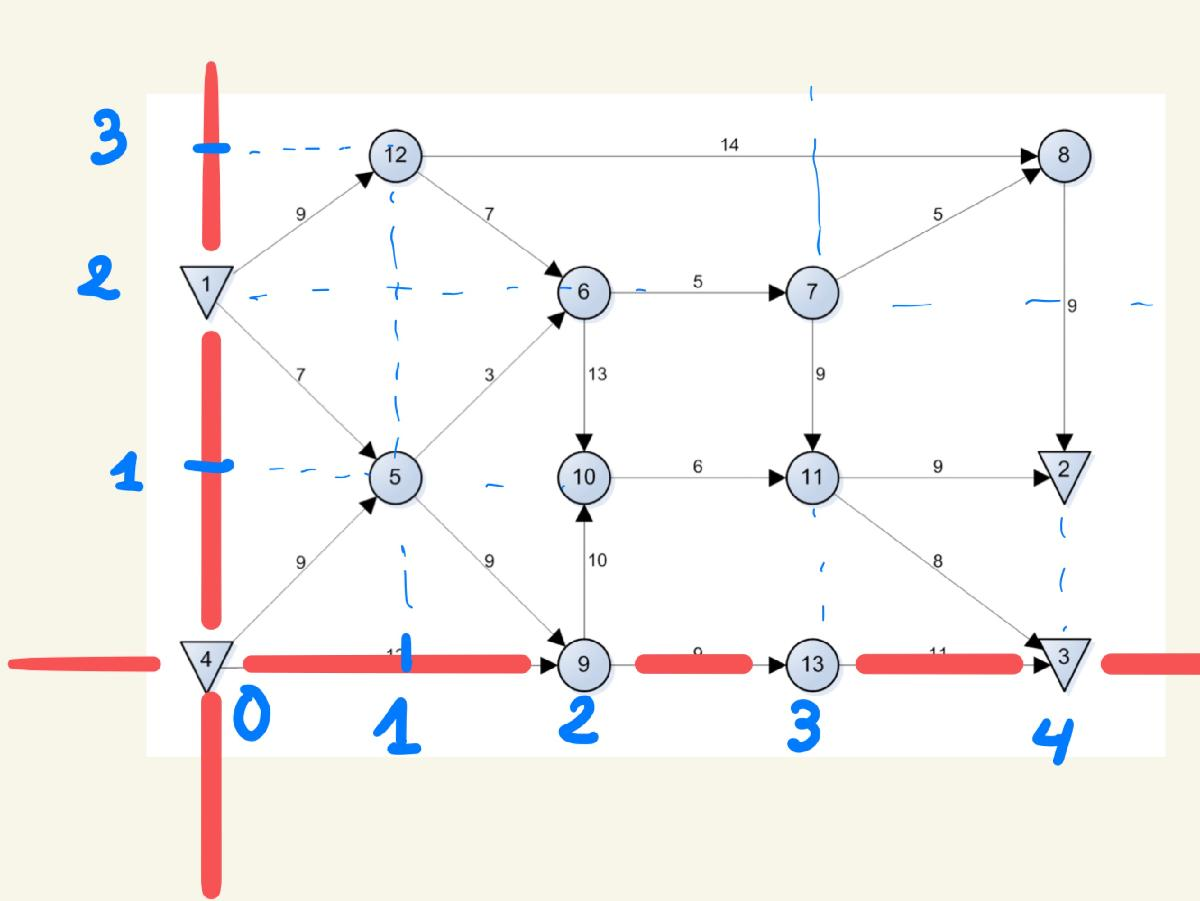

La figura es una estructura que contiene todas las opciones que pueden ser cambiadas. Veamos estas opciones para nuestro dibujo:

p1

p1 =   GraphPlot with properties:

     NodeColor: [0 0.4470 0.7410]
    MarkerSize: 4
        Marker: 'o'
     EdgeColor: [0 0.4470 0.7410]
     LineWidth: 0.5000
     LineStyle: '-'
     NodeLabel: {'1'  '2'  '3'  '4'  '5'  '6'  '7'  '8'  '9'  '10'  '11'  '12'  '13'}
     EdgeLabel: {}
         XData: [2 2 3 3 2.5000 2.5000 2 1.5000 3.5000 3 2.5000 1 4]
         YData: [6 1 1 6 5 4 3 2 4 3 2 5 3]
         ZData: [0 0 0 0 0 0 0 0 0 0 0 0 0]

  Show all properties


Se puede especificar otras coordenadas X, Y y Z (al ser un sistema de tres coordenadas este se puede representar en 3D).  El valor de las coordenadas X e Y se genera automáticamente por MATLAB. En las siguientes instrucciones se modifican estos valores según el sistema coordenado creado. Por ejemplo, en el grafo que queremos obtener, el nodo 1 tiene coordenadas (0,2) y por ese motivo la primera componente del vector de X es 0 y la primera componente del vector de Y es 2.

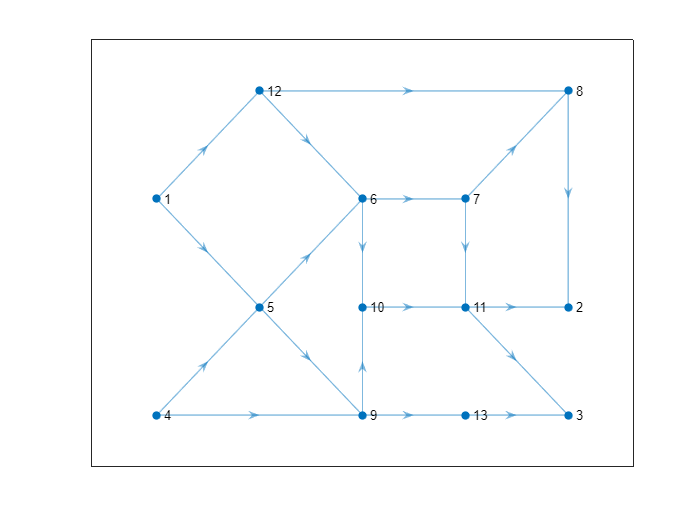

figure(3) 
G2 = digraph(source_nodes1, target_nodes1, edge_weights1);
p2 = plot(G2);
p2.XData=[0,4,4,0,1,2,3,4,2,2,3,1,3]; % coordenadas X de los nodos 
p2.YData=[2,1,0,0,1,2,2,3,0,1,1,3,0]; % coordenadas Y de los nodos

Ahora se puede comprobar que la representación obtenida del grafo es similar a la proporcionada en la Figura proporcioanda anteriormente.

#### Grosor de líneas

A continuación, se va a ilustrar como se puede modificar también el grosor de las arístas del grafo. Para ello, en este ejemplo vamos a representar las líneas del grafo con un grosor proporcional al peso del mismo.

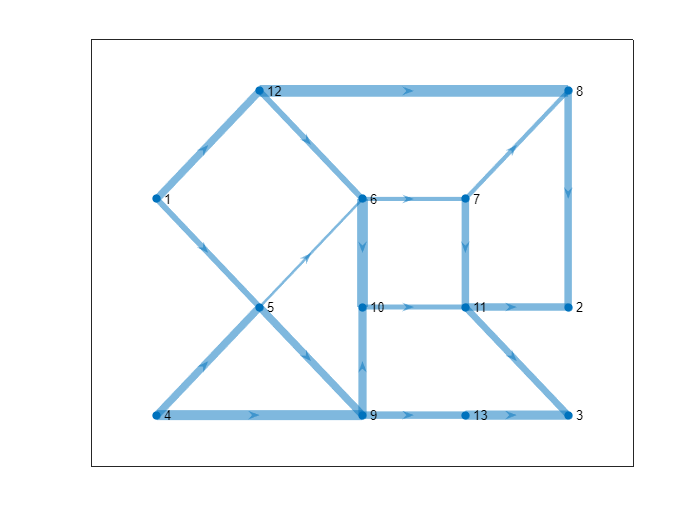

figure(4)
G3 = digraph(source_nodes1, target_nodes1, edge_weights1);
p3 = plot(G3);
G3.Edges.LWidths = 7*G3.Edges.Weight/max(G3.Edges.Weight);
p3.XData=[0,4,4,0,1,2,3,4,2,2,3,1,3];
p3.YData=[2,1,0,0,1,2,2,3,0,1,1,3,0];
p3.LineWidth = G3.Edges.LWidths;

#### Cambio de propiedades de nodos

También se pueden cambiar las propiedades de los nodos representados gráficamente. Primero vamos a visualizar que opciones tiene la estructura que contiene el dibujo del grafo:

p3 % campos de la estructura p3

p3 =   GraphPlot with properties:

     NodeColor: [0 0.4470 0.7410]
    MarkerSize: 4
        Marker: 'o'
     EdgeColor: [0 0.4470 0.7410]
     LineWidth: [3.5000 4.5000 4.5000 6 1.5000 4.5000 2.5000 6.5000 2.5000 4.5000 4.5000 5 4.5000 3 4.5000 4 3.5000 7 5.5000]
     LineStyle: '-'
     NodeLabel: {'1'  '2'  '3'  '4'  '5'  '6'  '7'  '8'  '9'  '10'  '11'  '12'  '13'}
     EdgeLabel: {}
         XData: [0 4 4 0 1 2 3 4 2 2 3 1 3]
         YData: [2 1 0 0 1 2 2 3 0 1 1 3 0]
         ZData: [0 0 0 0 0 0 0 0 0 0 0 0 0]

  Show all properties


En este ejemplo vamos a modificar el tamaño de la representación del nodo, de la fuente con que se escribe el número del nodo y el tamaño de las flechas:

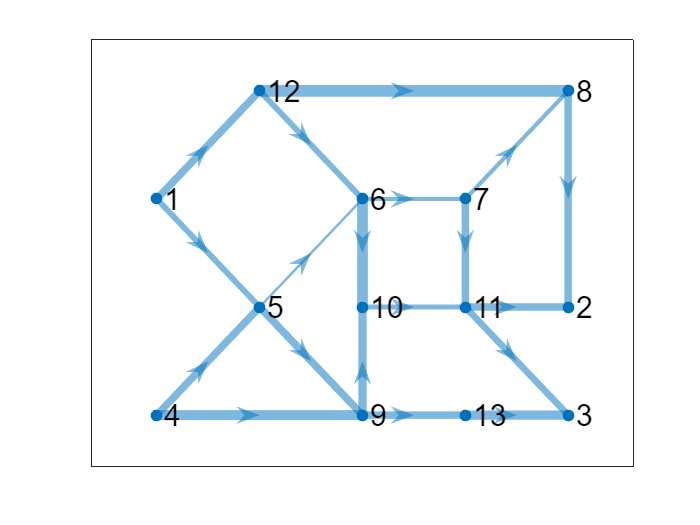

figure(5)
G4 = digraph(source_nodes1, target_nodes1, edge_weights1);
p4 = plot(G4);
G4.Edges.LWidths = 7*G4.Edges.Weight/max(G4.Edges.Weight);
p4.XData=[0,4,4,0,1,2,3,4,2,2,3,1,3];
p4.YData=[2,1,0,0,1,2,2,3,0,1,1,3,0];
p4.LineWidth = G4.Edges.LWidths;
p4.MarkerSize=6;     % tamaño de la marca
p4.NodeFontSize=18;  % tamaño de la etiqueta
p4.ArrowSize=14;     % tamaño de la flecha indica sentido

## 2. Algoritmos de caminos mínimos

Una vez que hemos estudiado cómo se pueden representar grafos usando MATLAB, en esta sección veremos como cálcular el camino mínimo entre dos nodos en un grafo pesado (en el que todas las aristas tienen asignado un número positivo, su peso). 

En un grafo pesado, la longitud de un camino es la suma de los pesos de las aristas del camino. Si $u$ y $v$ son nodos (o vértices) del grafo, la distancia de $u$ a $v$ es el mínimo de las longitudes de los caminos con origen en $u$ y extremo en $v$. Si no existe ningún camino entre ambos nodos, entonces la distancia será $\infty$.

Hay diversos algoritmos para calcular el camino mínimo entre dos nodos de un grafo. Uno de los más famosos es el algoritmo de Dijkstra, el cual requiere que todos los pesos de las aristas sean positivos. MATLAB implementa este y otros algoritmos bajo la función *shortestpath(G,s,t,'Method','method_name')*.

En dicha función se requieren los siguientes parámetros:

- G - El grafo.

- s - El nodo inicial del camino.

- t - El nodo final del camino.

- 'method_name' - El algoritmo a utilizar. Si no se especifica, por ejemplo usando *shortestpath(G,s,t)*, entonces MATLAB utiliza la opción *'auto'*, la cual selecciona utomáticamente el algoritmo más apropiado. En nuestro caso usaremos esta opción, ya que MATLAB seleccionará automaticamente el algoritmo de Dijkstra. 

### Costes generales

Primero vamos a definir un grafo pesado. También lo vamos a representar.

figure(6)
G5 = digraph(source_nodes1, target_nodes1, edge_weights1);
p5 = plot(G5);
nodeIDs=[6 8]; % Nodos a eliminar
G_agujereada = rmnode(G5,nodeIDs)

G_agujereada =   digraph with properties:

    Edges: [12×2 table]
    Nodes: [11×0 table]


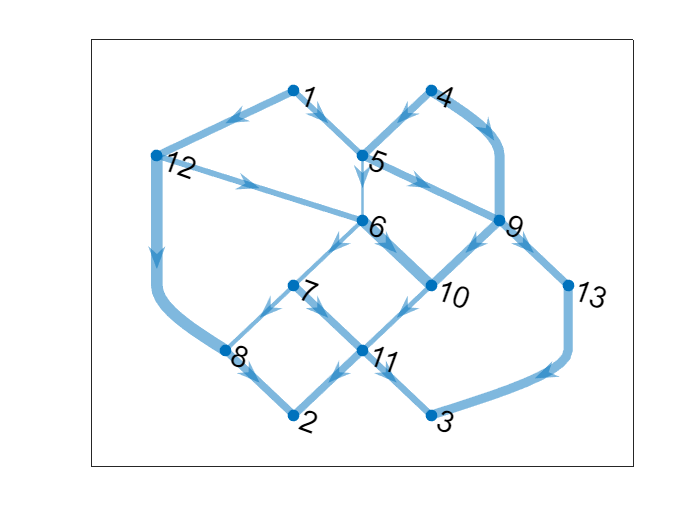

G5.Edges.LWidths = 7*G5.Edges.Weight/max(G5.Edges.Weight);
%p5.XData=[0,4,4,0,1,2,3,4,2,2,3,1,3]; Descomentar
%p5.YData=[2,1,0,0,1,2,2,3,0,1,1,3,0];
p5.LineWidth = G5.Edges.LWidths;
p5.MarkerSize=6;     % tamaño de la marca
p5.NodeFontSize=18;  % tamaño de la etiqueta
p5.ArrowSize=14;     % tamaño de la flecha indica sentido

A continuación, vamos a calcular el camino mínimo entre los nodos 1 y 3 utilizando la función explicada anteriormente:

% calculamnos el camino minimo en el grafo G5 entre los vértices 1 y 3
path = shortestpath(G5,1,3)

path =      1     5     6     7    11     3


Observar que la llamada a la función nos devuelve un vector conteniendo los nodos que componen el camino mínimo. En nuestro caso el camino mínimo entre los nodos 1 y 3 es: 1, 5, 6, 7, 11, 3.

Vamos a resaltar el camino mínimo obtenido anteriormente en la representación del grafo. Para ello vamos a utilizar la función *highlight()* la cual permite resaltar tanto nodos como arístas en un grafo:

% Dibujamos en la gráfica p5 los nodos 1 y 3 en grande
highlight(p5,[1 3])
path = shortestpath(G_agujereada,1,3)

path =      1     5     7    11     3


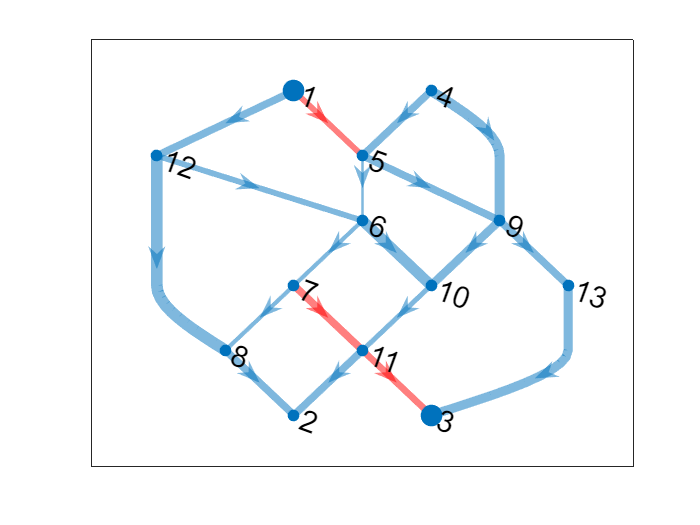

% Resaltamos el camino mínimo path en rojo en la gráfica p5
highlight(p5,path,'EdgeColor','r')

### Costes iguales

Consideremos ahora que todos los costes tienen el mismo valor. Esto es lo mismo a que todas las aristas tuviera peso 1, por lo tanto, queremos calcular el camino con menor números de arcos entre dos nodos dados. Para ello, es suficiente con modificar el algoritmo utilizado para calcular el caminio mínimo. Especificando la opción '*unweighted*', MATLAB trata todas las aristas como si tuvieran un peso de 1:

path1 = shortestpath(G5,1,3,'Method','unweighted') % Igual coste para todas las aristas

path1 =      1     5     9    13     3


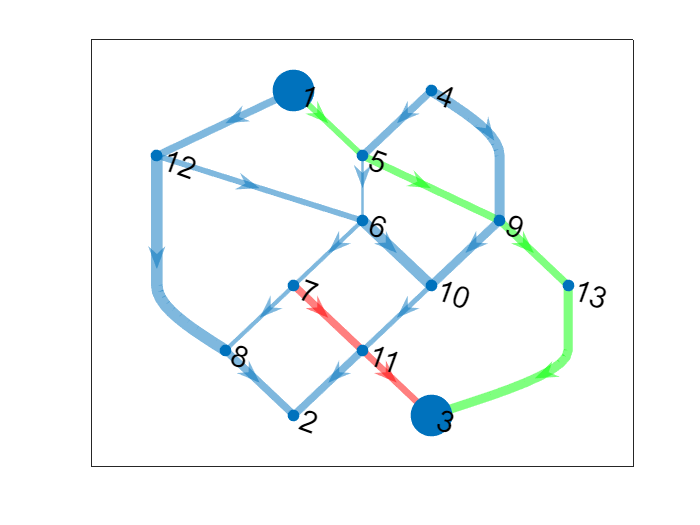

hold on % Diujamos en la misma figura el primer y el segundo camino
% Dibujamos en la gráfica p5 los nodos 1 y 3 en grande
highlight(p5,[1 3]) 

% Resaltamos el camino mínimo path en rojo en la gráfica p5
highlight(p5,path,'EdgeColor','r')

% Ahora resaltamos en verde el camino mínimo considerando costes iguales
highlight(p5,path1,'EdgeColor','g')

## 3. Trayectoria 2D de un robot

Se considera un grafo que representa una cuadrícula de 10 x 10. Esta cuadrícula es el espacio por donde se mueve el robot. Los obstáculos se depositan encima de la cuadrícula, eliminando los nodos sobre los que cae. El coste de los arcos es la distancia entre los nodos. Se busca calcular la trayectoria del robot de un punto a otro de la cuadrícula, evitando los obstáculos, y con el menor coste (es decir, menor distancia recorrica). Lo que se busca por tanto es calcular el camino mínimo sobre dicho grafo. Notar que este problema está planteado en un espacio 2D pero tamién se puede extender a grafos en 3D. En MATLAB existe la posibilidad de representar los grafos en 3D, como ya se ha mencionado.

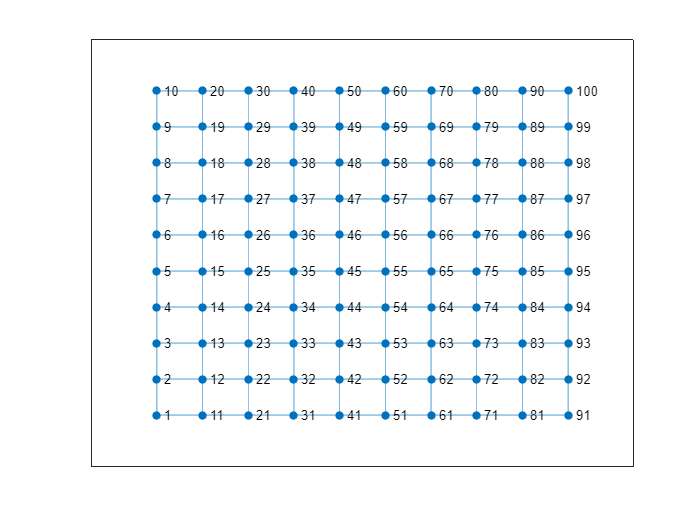

% Contruir una malla de 10 X 10
source_nodes = []; % Notar que los nodos pueden proporcionarse como un cell de string, 
% un cell de chars, o un vector de enteros.
target_nodes = []; %
edge_weights = []; %
for i=1:90 % arcos horizontales
    source_nodes=[source_nodes,i];
    target_nodes = [target_nodes,i+10];
end
for i=1:100 % arcos verticales
    if mod(i,10) ~= 0
        source_nodes=[source_nodes,i];
        target_nodes = [target_nodes,i+1];
    end
end

% Definición del grafo
malla = graph(source_nodes, target_nodes, edge_weights);
figure(7)
G_malla=plot(malla);
% Representación con aspecto de rejilla. Los nodos se sitúan
% correlativamente en columnas de abajo a arriba. Primera columna del 1 al
% 10, segunda columna del 11 al 20, así sucesivamente
G_malla.XData=[ones(1,10) 2*ones(1,10) 3*ones(1,10) 4* ones(1,10) ...
    5* ones(1,10) 6* ones(1,10) 7* ones(1,10) 8*ones(1,10) 9* ones(1,10) ...
    10* ones(1,10)]; % Coordenadas X de los nodos 
% Notar que repmat permite repetir copias de un mismo array
G_malla.YData=repmat(1:10,[1,10]); % Coordenadas Y de los nodos

A continuación vamos a eliminar siete nodos por los que el robot no se puede mover, por estar situado un obstáculo encima de ellos.

% Agujereamos la malla
figure(8)
nodeIDs=[47,57,48,56,66,76,75];             % Nodos a eliminar
Malla_agujereada = rmnode(malla,nodeIDs)    % Eliminacion de nodos

Malla_agujereada =   graph with properties:

    Edges: [158×1 table]
    Nodes: [93×0 table]


Vamos a dibujar la malla agujereada. Al eliminar los nodos tenemos que redefinir las coordenadas de los nodos que permanecen, para poder dar su representación en el plano.

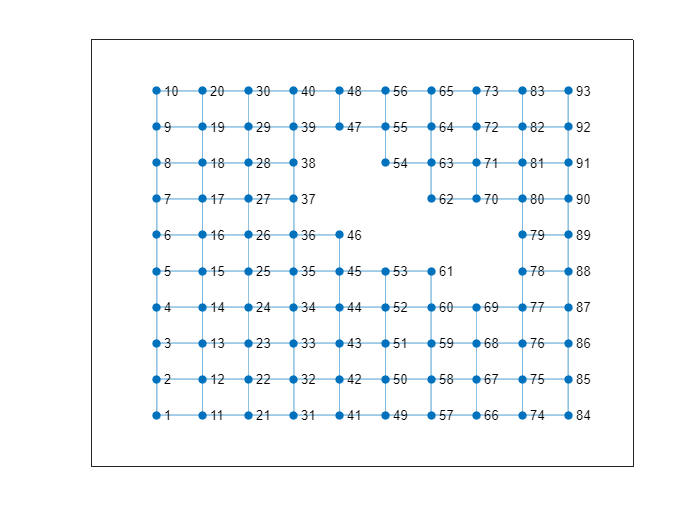

% Representación de la malla agujereada
G_malla_agujereada=plot(Malla_agujereada);
indices=[1:46 49:55 58:65 67:74 77:100]; % indices de nodos que permanecen en la malla
x=[ones(1,10) 2*ones(1,10) 3*ones(1,10) 4* ones(1,10) 5* ones(1,10) 6* ones(1,10) 7* ones(1,10) 8*ones(1,10) 9* ones(1,10) 10* ones(1,10) ]; 
y=repmat(1:10,[1,10]);
G_malla_agujereada.XData=x(indices); % Extraigo las coordenadas X de los nodos que permanecen en la malla, las posiciones indices
G_malla_agujereada.YData=y(indices); % Idem con la coordenada y

Sobre el grafo resultante calculamos el algoritmo de camino mínimo, considerando que todos los arcos tienen el mismo coste. Como es una malla los nodos están sobre cuadrados y su longitud es la misma. Vamos a calcular el recorrido entre los dos extremos de la malla, que se corresponde en el grafo anterior con los nodos 1 y 93.

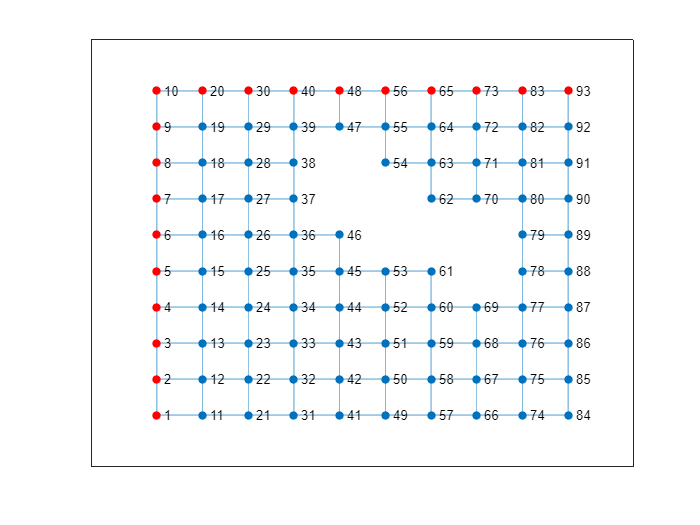

% Calculamos el camino mínimo evitando el agujero
trayectoria = shortestpath(Malla_agujereada,1,93,'Method','unweighted');
hold on; % Permite dibujar encima del plot anterior
highlight(G_malla_agujereada,trayectoria,'NodeColor','r')

Notar que se ha obtenido uno de los múltiples caminos mínimos existentes, ya que hay varias soluciones en este caso.